# Reprezentacja układów liniowych niezmienniczych w czasie w Matlabie

Mateusz Wójcik, 09.10.2024

## Reprezentacja układów liniowych niezmienniczych w czasie w Matlabie

settings.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";

## Wstęp

Materiał omawiany na zajęciach będzie dotyczył między innymi: implementacji transformaty Laplace'a, zapisywaniu transmitancji operatorowej obiektów, rozważenie przykładu  obliczeń dla zawieszenia samochodowego, zapisywania równań przestrzeni stanów oraz łączenia modelów.

## Matematyczna reprezentacja transformaty Laplace'a

syms t s;
syms a positive;

Definicja funkcji Heaviside

f = heaviside(t-a)

$$f = \mathrm{heaviside}\left(t-a\right)$$

Fs = laplace(f,t,s)

$$Fs = \frac{{\mathrm{e}}^{-a\,s}}{s}$$

f = subs(f,a,1);
fs = subs(Fs,a,1);

## Zad 1

Wyświetlono funkcję Heaviside'a przy pomocy funkcji fplot, która zastąpiła w nowszych wersjach funkcję ezplot.

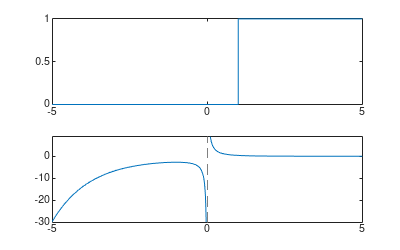

subplot(211)
fplot(f);

subplot(212)
fplot(fs)
set(gcf,'position',[0,0,400,250]);

## Transmitancja

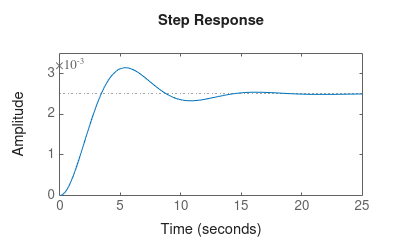

licz = [0 0 1];
mian = [1000 500 400];

clf
step(licz, mian)

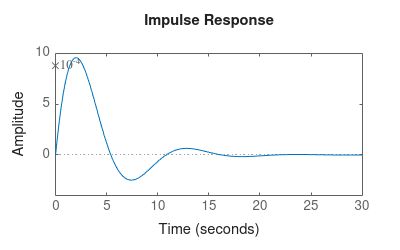

impulse(licz, mian)

obiekt = tf(licz, mian);
get(obiekt)

       Numerator: {[0 0 1]}
     Denominator: {[1000 500 400]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



step(obiekt)

impulse(obiekt)

% Szukanie biegunów
[z, p, k] = tf2zp(licz, mian)


z =

  0×1 empty double column vector



p =   -0.2500 + 0.5809i
  -0.2500 - 0.5809i


k = 1.0000e-03

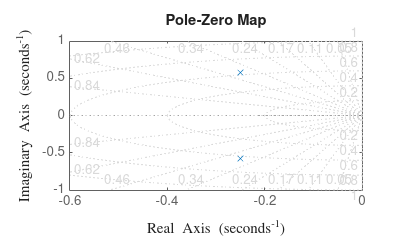

% Wyświetlanie na płaszczyźnie zespolonej
pzmap(p, z)
grid on
axis([-0.6 0 -1 1])

pzmap(licz, mian)
grid on
axis([-0.6 0 -1 1])

pzmap(obiekt)
grid on
axis([-0.6 0 -1 1])

## Zad 2a

- Bieguny nie są rzeczywiste i wynoszą kolejno: -0.2500 + 0.5809i oraz-0.2500 - 0.5809i

- Układ jest stabilny, ponieważ jak wydac po powyższych wykresach wartość odpowiedzi dązy do stałej wartości w czasie.

syms c M alpha
c = 400;
M = 1000;

%%
K = 1/c;
T = 2*sqrt(M/c);
xi = alpha/(2*sqrt(c*M));
mian_t = [T^2 2*T*xi 1]

$$mian\_t = \left(\begin{array}{ccc} 10 & \frac{8796093022208\,\sqrt{10}\,\alpha }{5563137692178265} & 1 \end{array}\right)$$

licz_zawieszenie = [ 0 0 K]

licz_zawieszenie =          0         0    0.0025


mian_zawieszenie = eval(subs(mian_t, alpha, 500));

## Zad 2b

[z2, p2, k2] = tf2zp([0 0 K], mian_t);


**Dla alpha = 500, otrzymano bieguny zespolone**

eval(subs(p2,alpha, 500))

ans =   -0.1250 - 0.2905i
  -0.1250 + 0.2905i


Wzmocnienie, jest niezależne od parametru alpha:

k2 

k2 = 2.5000e-04

Funkcja w postaci sfaktoryzowanej:


$$G(s) = \frac{K}{T^2} \cdot \frac{1}{s^2 +\frac{2\xi}{T}s + \frac{1}{T^2}} = \frac{1}{4M} \cdot \frac{K}{T^2} \cdot \frac{1}{s^2 +\frac{2\xi}{T}s + \frac{1}{T^2}} = \frac{2,5 \cdot 10^{-4}}{(s+0.1250 + 0.2905i)(s + 0.1250 - 0.2905i)}$$
 

## zad 2c

Przypadek tłumiony: $\xi = 1$

alpha_t = eval(solve(xi - 1, alpha))

alpha_t = 1.2649e+03

obiekt_t = tf([0 0 K], eval(subs(mian_t, alpha, alpha_t)))


obiekt_t =
 
         0.0025
  --------------------
  10 s^2 + 6.325 s + 1
 
Continuous-time transfer function.
Model Properties


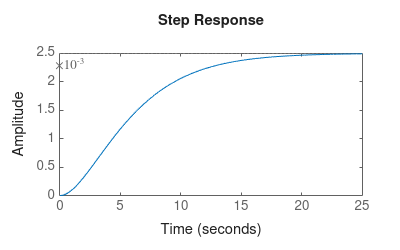

step(obiekt_t)

Przypadek oscylacyjny: $\xi = 0.5$

alpha_o = eval(solve(xi - 0.5, alpha))

alpha_o = 632.4555

obiekt_o = tf([0 0 K], eval(subs(mian_t, alpha, alpha_o)))


obiekt_o =
 
         0.0025
  --------------------
  10 s^2 + 3.162 s + 1
 
Continuous-time transfer function.
Model Properties


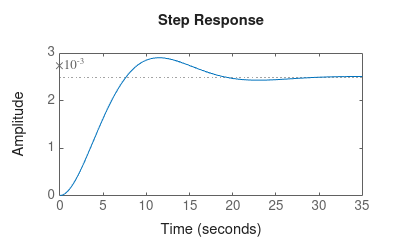

step(obiekt_o)

## Zera, bieguny, wzmocnienie

[licz, mian] = zp2tf(-1/3, [0 -1 -3], 3);
printsys(licz, mian);

 
num/den = 
 
        3 s + 1
   -----------------
   s^3 + 4 s^2 + 3 s


obiekt = zpk(-1/3, [0, -1 -3], 3)


obiekt =
 
  3 (s+0.3333)
  -------------
  s (s+1) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


## Zad 3

Tworzenie obiektu o transmitancji:


$$G(s) = \frac{2\cdot (s + 0,25)}{s(s+5)(s+0,1)}$$


obiekt_zaadanie = zpk(-0.25, [-5, -0.1], 2)


obiekt_zaadanie =
 
   2 (s+0.25)
  -------------
  (s+5) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


## Przestrzeń stanów

Tworzenie przestrzeni stanów (State Space)

c = 400;
M = 1000;
alpha = 500;
F = 1000;

Zapisanie odpowiednich macierzy:

A = [[0 1]; [-c/M -alpha/M]];
B = [0; 1/M];
C = [1 0];
D = 0;

Zdefiniowanie obiektu

obiekt = ss(A,B,C,D)


obiekt =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.4  -0.5
 
  B = 
          u1
   x1      0
   x2  0.001
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Wyświetlenie odpowiedzi skokowej i impulsowej przy użyciu różnych metod

clf
step(obiekt)

clf
impulse(obiekt)

clf
impulse(A, B, C, D)

**Zero-Pole to State Space **

[~,~,~,~] = zp2ss(z,p,k)

A =    -0.5000   -0.6325
    0.6325         0


B =      1
     0


C =          0    0.0016


D = 0

**Transfere Function to State Space**

[A,B,C,D] = tf2ss(licz,mian)

A =     -4    -3     0
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     3     1


D = 0

Wzmocnienie w stanie ustalonym

k = dcgain(A,B,C,D)

k = Inf

## Zad 4

**Transfer Function to State Space**

[A_tf, B_tf, C_tf, D_tf] = tf2ss(licz_zawieszenie, mian_zawieszenie)

A_tf =    -0.2500   -0.1000
    1.0000         0


B_tf =      1
     0


C_tf = 1.0e-03 *

         0    0.2500


D_tf = 0

**Zero-Pole to State Space**

[z_zawieszenie, p_zawieszenie, k_zawieszenie] = tf2zp(licz_zawieszenie, mian_zawieszenie);
[A_zp, B_zp, C_zp, D_zp] = zp2ss(z_zawieszenie, p_zawieszenie, k_zawieszenie)

A_zp =    -0.2500   -0.3162
    0.3162         0


B_zp =      1
     0


C_zp = 1.0e-03 *

         0    0.7906


D_zp = 0

Wyniki obu metod różnią się od siebie. Rozważmy macierz A_x:

A_tf - A_zp

ans =          0    0.2162
    0.6838         0


Różnica obu macierzy nie jest macierzą zerową, ani liczbą bliską błędowi obliczeniowemu, zatem obie macierze się istotnie różnią. Wynika to prawdopodobnie z różnic implementacyjnych obu rozważanych metod w środowisku Matlab, o czym jest mowa w oficjalnej dokumentacji. Istotnym faktem jest natomiast zauważenie, że obie macierze A mają te same wartości własne.

eig(A_tf)

ans =   -0.1250 + 0.2905i
  -0.1250 - 0.2905i


eig(A_zp)

ans =   -0.1250 + 0.2905i
  -0.1250 - 0.2905i


## Łączenie modeli

sys1 = tf([0 0 4], [100 200 300]);
sys2 = tf([0 0 1], [600 500 400]);


**Połączenie szeregowe**

sys_szereg1 = series(sys1, sys2)


sys_szereg1 =
 
                             4
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 120000
 
Continuous-time transfer function.
Model Properties


sys_szereg2 = sys1 * sys2


sys_szereg2 =
 
                             4
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 120000
 
Continuous-time transfer function.
Model Properties


**Połączenie równoległe**

sys_rown1 =  parallel(sys1, sys2)


sys_rown1 =
 
                 2500 s^2 + 2200 s + 1900
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 120000
 
Continuous-time transfer function.
Model Properties


sys_rown2 = sys1 + sys2


sys_rown2 =
 
                 2500 s^2 + 2200 s + 1900
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 120000
 
Continuous-time transfer function.
Model Properties


**Sprzężenie zwrotne:**

a) ujemne:

sys_minus_feedback = feedback(sys1,sys2)


sys_minus_feedback =
 
                 2400 s^2 + 2000 s + 1600
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 120004
 
Continuous-time transfer function.
Model Properties


b) dodatnie:

sys_plus_feedback = feedback(sys1,sys2,+1)


sys_plus_feedback =
 
                 2400 s^2 + 2000 s + 1600
  -------------------------------------------------------
  60000 s^4 + 170000 s^3 + 320000 s^2 + 230000 s + 119996
 
Continuous-time transfer function.
Model Properties


## Zad 5

Zadanie rozpoczęto od stworzenia obiektów o podanych w zadaniu transmitancjach, przy pomocy Transfer Function.

sys1 = tf([0 1 1], [1 5 1]);
sys2 = tf([0 0 0 1], [1 1 -2 1]);

Przy pomocy pokazanych wcześniej metod stworzono odpowienie transmitancje: 

**1.Połączenie szeregowe**

sys_szereg = sys1 * sys2


sys_szereg =
 
                  s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


**2.Połączenie równoległe**

sys_rown = sys1 + sys2


sys_rown =
 
          s^4 + 2 s^3 + 4 s + 2
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


**3. Ujemne sprzężenie zwrotne**

sys_feedback = feedback(sys1,sys2)


sys_feedback =
 
        s^4 + 2 s^3 - s^2 - s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 4 s + 2
 
Continuous-time transfer function.
Model Properties


## Wnioski

Na zajęciach zapoznano się z różnymi sposobami podstawowego opisu elementów automatyki przy użycia oprogramowania Matlab. Ciekawym spostrzeżeniem jest fakt, że w zależności od sposobu przechodzenia do przestrzeni stanów, w zależności czy zaczynamy od zero-pole, czy transform function. Pozytywne wrażenie robi również łatwość szybkiego, poglądowego narysowania wykresów do wstępnej analizy. 